# Kinematics. RTB introduction

clear all
close all
clc

## 2D Rotation Matrix 


$$
\[{}_B^A{R_{2x2}} = {\left[ {\begin{array}{*{20}{c}}
  {{{\hat X}^T}_A} \\ 
  {{{\hat Y}_A}^T} 
\end{array}} \right]_{2x2}}{\left[ {\begin{array}{*{20}{c}}
  {{{\hat X}_B}}&{{{\hat Y}_B}} 
\end{array}} \right]_{2x2}}= {{}^0RF_A^T}
 {{}^0R{F_B}}$$


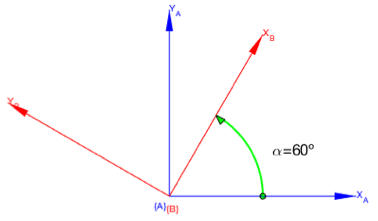

### Unitary vector

alpha=60*pi/180 % In [rad]

alpha = 1.0472

B=[[cos(alpha) sin(alpha)]' [-sin(alpha) cos(alpha)]']

B =     0.5000   -0.8660
    0.8660    0.5000


A= eye(2)

A =      1     0
     0     1


R_BA=A'*B

R_BA =     0.5000   -0.8660
    0.8660    0.5000


### Symbolic representation

syms alpha real
B=[[cos(alpha) sin(alpha)]' [-sin(alpha) cos(alpha)]']

$$B = \left(\begin{array}{cc} \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

### RTB 'rot2' function

B = rot2(alpha) % RTB save time 

$$B = \left(\begin{array}{cc} \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

## Rotation Matrix. ${}^A_BR$Example

syms alpha beta real
A=rot2(alpha) % wrt  RF {I} Inertial Frame

$$A = \left(\begin{array}{cc} \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

B=rot2(beta)% wrt  RF {I} Inertial Frame

$$B = \left(\begin{array}{cc} \cos\left(\beta \right) & -\sin\left(\beta \right)\\ \sin\left(\beta \right) & \cos\left(\beta \right) \end{array}\right)$$


R_BA=A'*B

$$R\_BA = \left(\begin{array}{cc} \sin\left(\alpha \right)\,\sin\left(\beta \right)+\cos\left(\alpha \right)\,\cos\left(\beta \right) & \cos\left(\beta \right)\,\sin\left(\alpha \right)-\cos\left(\alpha \right)\,\sin\left(\beta \right)\\ \cos\left(\alpha \right)\,\sin\left(\beta \right)-\cos\left(\beta \right)\,\sin\left(\alpha \right) & \sin\left(\alpha \right)\,\sin\left(\beta \right)+\cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$

R_BA=simplify(R_BA)

$$R\_BA = \left(\begin{array}{cc} \cos\left(\alpha -\beta \right) & \sin\left(\alpha -\beta \right)\\ -\sin\left(\alpha -\beta \right) & \cos\left(\alpha -\beta \right) \end{array}\right)$$

R_BA=subs(R_BA,[alpha,beta],[40,75]) % in degrees

$$R\_BA = \left(\begin{array}{cc} \cos\left(35\right) & -\sin\left(35\right)\\ \sin\left(35\right) & \cos\left(35\right) \end{array}\right)$$

### Numerical substitution

alpha=40*pi/180 % in radians

alpha = 0.6981

beta=75*pi/180

beta = 1.3090

R_BA=[[cos(alpha-beta) -sin(alpha-beta)]' [sin(alpha-beta) cos(alpha-beta)]']

R_BA =     0.8192   -0.5736
    0.5736    0.8192


R_BA=rot2(alpha)'*rot2(beta) % Straight forward

R_BA =     0.8192   -0.5736
    0.5736    0.8192


## 3D pose: Frame Description


$$ {}_B^AT = {\left[ {\begin{array}{*{20}{c}}
  {{}_B^A{R_{3x3}}}&{{}^A{P_{BOR{G_{3x1}}}}} \\ 
  {{{\begin{array}{*{20}{c}}
  0&0&0 
\end{array}}_{1x3}}}&1 
\end{array}} \right]_{4x4}}
  \therefore Going{\text{ from \{ A\} }} \to \{ {\text{B\} }}
  {}_B^AT = transl({P_{BORG}})Rot(\alpha \beta \phi ) 
\end{gathered} \]$$


T1= transl2(1, 2) * trot2(30, 'deg') % frame description 

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


T11=transl2(1,2)

T11 =      1     0     1
     0     1     2
     0     0     1


T11= [[eye(2) ;[0 0]] [1 2 1]']

T11 =      1     0     1
     0     1     2
     0     0     1


T12=trot2(30,'deg')

T12 =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


T12= [[rot2(30,'deg');[0 0]] [0 0 1]']  

T12 =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


T1=T11*T12

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


T1= transl2(1, 2) * trot2(30, 'deg')

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


### Displaying Frame

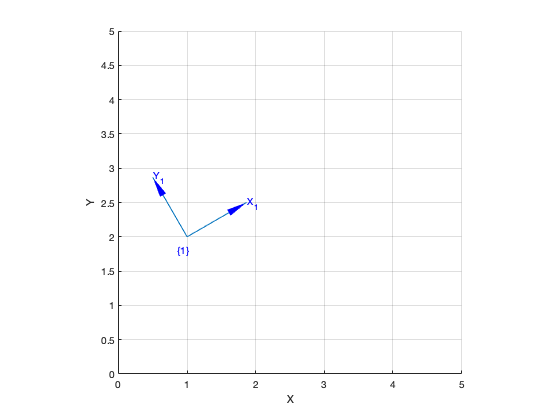

plotvol([0 5 0 5]); % RTB
trplot2(T1, 'frame', '1', 'color', 'b','length',1 ,'width', 1,'arrow' )% RTB

### Animation


$${}_B^AT = transl({P_{BORG}})Rot(\alpha \beta \phi ) 
\end{gathered} \]$$


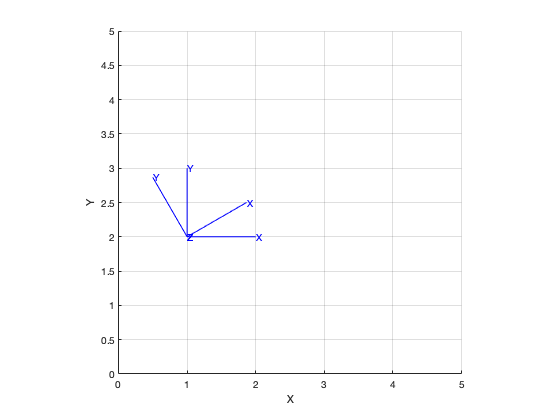

plotvol([0 5 0 5 0 1])
view(2)
tranimate(eye(4), transl(1,2,0),20)% RTB
hold on
tranimate(transl(1,2,0), transl(1,2,0)*trotz(30,'deg'))

## Understanding multiplication order

Frame Description/Operators

T1= transl2(1, 2) * trot2(30, 'deg'); % Frame description / Operator
T2 = transl2(2, 1)% Frame description / Operator

T2 =      1     0     2
     0     1     1
     0     0     1


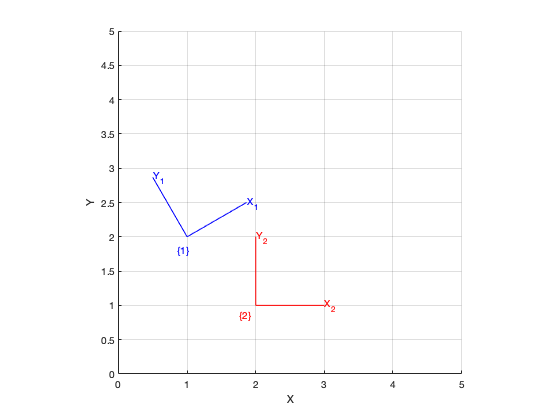

figure
plotvol([0 5 0 5 0 1])
view(2)
trplot2(T1, 'frame', '1', 'color', 'b')
hold on
trplot2(T2, 'frame', '2', 'color', 'r'); %Frame description
view(2)

### Postmultiplication

T3 = T1*T2 % Post multiplication = Been at T1  think in T2 as operator

T3 =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


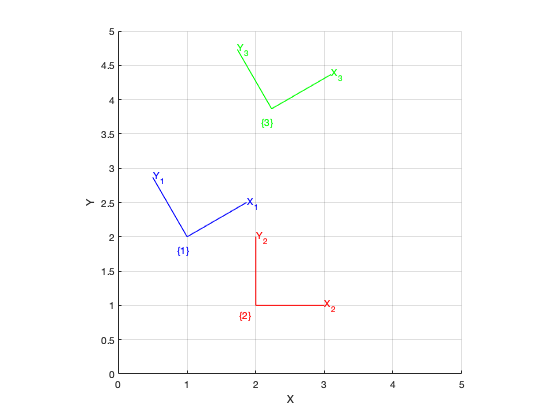

trplot2(T3, 'frame', '3', 'color', 'g');

See RF {3} wrt RF {1}

V = [[0 0; 2 0; 2 1; 0 1]'; [1 1 1 1]] % The translational part of T2 as vector in RF{1}

V =      0     2     2     0
     0     0     1     1
     1     1     1     1


See / mapped it in RF {U}

V_u=T1*V% P_a=T_b_a*P_b

V_u =     1.0000    2.7321    2.2321    0.5000
    2.0000    3.0000    3.8660    2.8660
    1.0000    1.0000    1.0000    1.0000


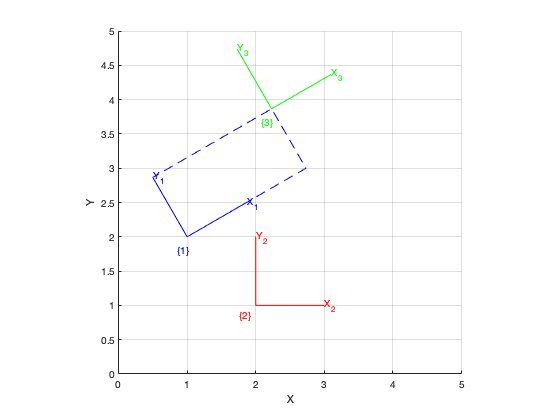

line(V_u(1,:),V_u(2,:),'Color','b','LineStyle','--')

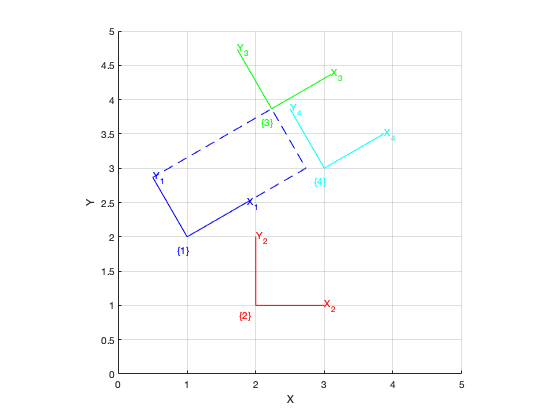

T4 = T2*T1; % Think in Post multiplication 
trplot2(T4, 'frame', '4', 'color', 'c');

## Mapping 

### Point in {U}

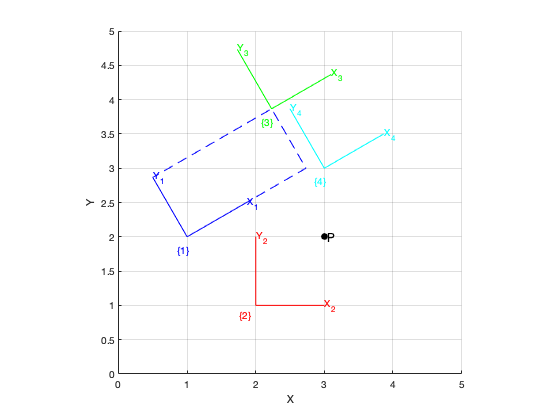

P = [3 ; 2 ];
plot_point(P, 'label', 'P', 'solid', 'ko'); %RTB

### Point in {1} and {2}


$$\[{}^AP = {}_B^AR{}^BP\] $$



$$\[{}^{\{ 1\} }P = {T_1}^{ - 1}{}^{\{ U\} }P\]$$


P1 = inv(T1) * [P; 1]

P1 =     1.7321
   -1.0000
    1.0000


P2 = inv(T2) * [P; 1]

P2 =      1
     1
     1


## Transform Operator

Given a point in Reference Frame {1} apply an operator. ¡Voila!

P % Remenber the point in {U}

P =      3
     2


PU=T1*P1

PU =     3.0000
    2.0000
    1.0000


## Transform compound Exercise 1

The next Figure is a hand made skecth representing a simplify robotic problem.


$$  It\;is\;know\;\left( {\begin{array}{*{20}{c}}
  {{}_F^UT}&{{}_F^IT}&{{}_R^UT} 
\end{array}} \right)\;\& \;{}^IP$$


## Draw a Matlab Figure and $Find\;{}^RP$

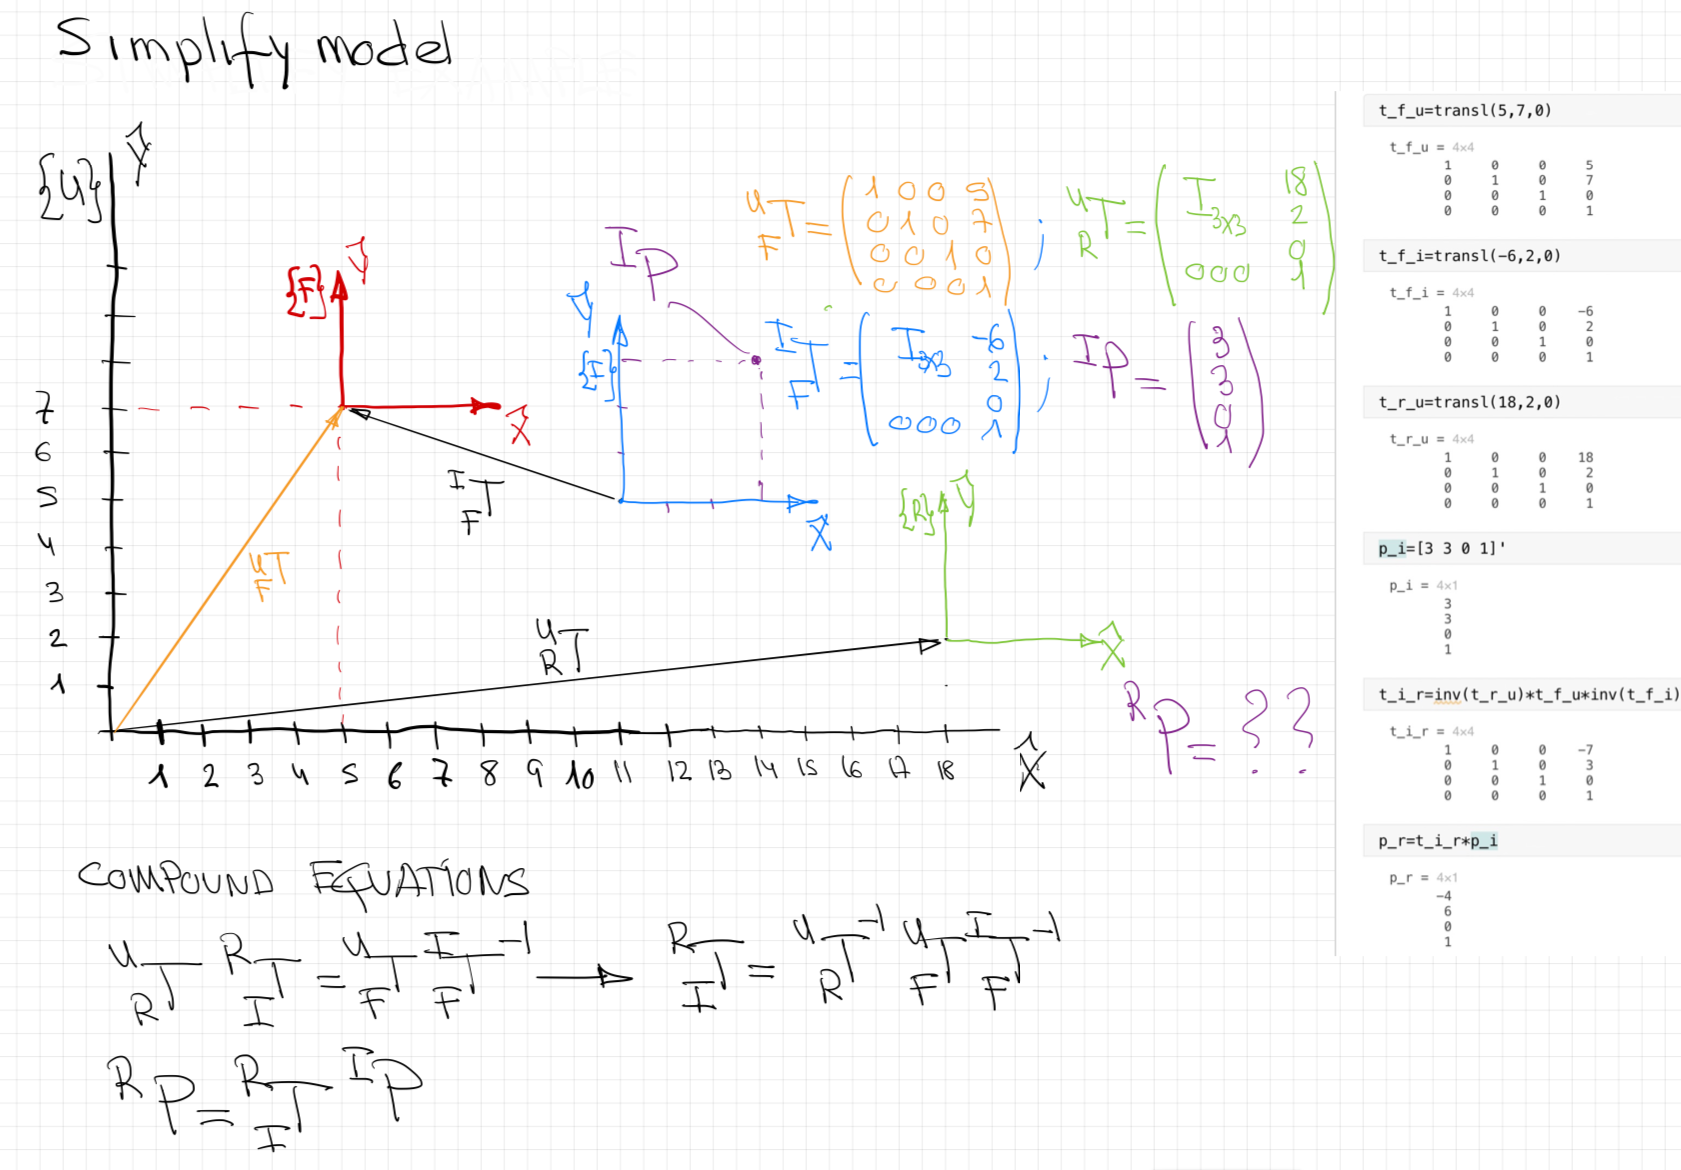

T_F_U=transl(5,7,0) % T_b_a
T_R_U=transl(18,2,0)*trotz(pi/2)
T_F_I=transl(-6,2,0)
P_I=[3 3 0 1]'
T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)
P_R=T_I_R*P_I

## Transform compound Exercise 2

See the video: [https://youtu.be/KZnt6XtVTtY](https://youtu.be/KZnt6XtVTtY)

### Organize your ideas and make and skecth 

Think about: 

- Vision system give you the kind of box (Small / Big) and the pose wrt Conveyor belt, i.e. T_caja_Conveyor

- There are two Pallets for boxes (Small / Big)

- Is not a 3D ploblem

Add your image here

### Draw a Matlab Figure and find ${}^R{P_{Caja}$

Define all References Frames {R}, {C} ,{B}, {P1},{P2}

Solve the equation